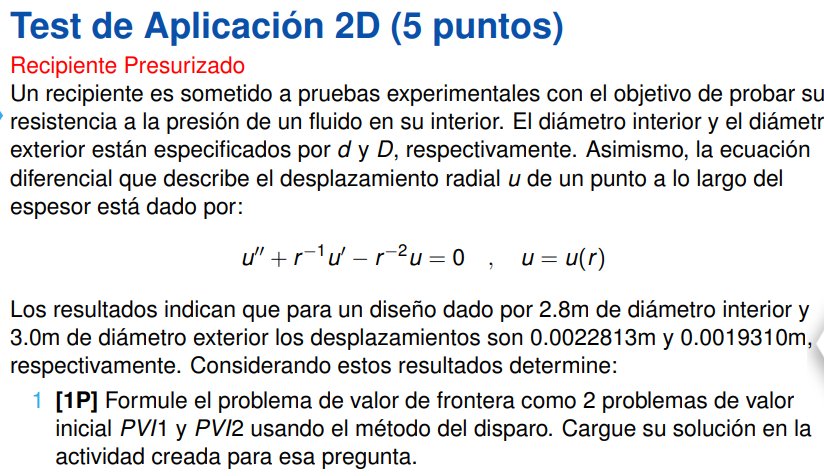

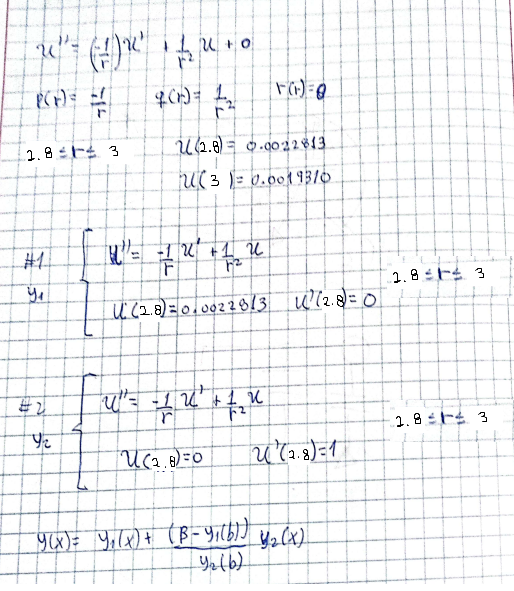

format long
h=0.04;
a=2.8;
b=3;
alfa = 0.0022813;
beta = 0.001931;

f = @(r,u) ( [ u(2); -u(2)/r+u(1)/(r^2) ]  );


% y1
y0 = [alfa;0];

sol1 = rk4(f,a,b,y0,h);

y1b = sol1(:,2)

y1b =    0.002281300000000
   0.002281529507179
   0.002282205278042
   0.002283308972983
   0.002284823243732
   0.002286731667255


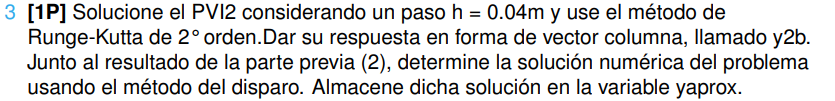

% y2
y0 = [0;1];

sol2 = rk2(f,a,b,y0,h);
y2b = sol2(:,2)

y2b =                    0
   0.039714285714286
   0.078881061413113
   0.117522820855784
   0.155660842365421
   0.193315269823151




alfa = 0.0022813;
beta = 0.001931;
yaprox = y1b + ((beta - y1b(end))/y2b(end))*y2b

yaprox =    0.002281300000000
   0.002208448735630
   0.002137051242786
   0.002067047789675
   0.001998381872434
   0.001931000000000


alpha = 0.0022813;
beta = 0.001931;

a=2.8;
b=3;

p= @(x) (-1./x);
q= @(x) (1/(x.^2));
r= @(x) (0*x);

h=0.04;

tmp = diferenciafinita(p,q,r,a,b,alpha,beta,h);

xi =    2.840000000000000
   2.880000000000000
   2.920000000000000
   2.960000000000000



ydiffin= [alpha; tmp; beta]

ydiffin =    0.002281300000000
   0.002208953248190
   0.002137618339062
   0.002067481925354
   0.001998501715530
   0.001931000000000


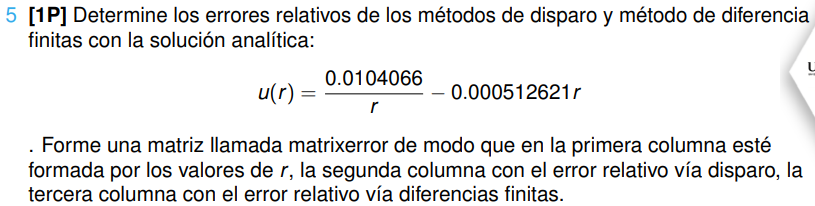


u = @(r) (0.0104066./r-0.000512621.*r)

u = function_handle with value:
    @(r)(0.0104066./r-0.000512621.*r)


a=2.8;
b=3;
h=0.04;

R = [a:h:b]'

R =    2.800000000000000
   2.840000000000000
   2.880000000000000
   2.920000000000000
   2.960000000000000
   3.000000000000000


U = u(R);

matrixerror=zeros(length(R),3);
matrixerror(:,1)=R;
matrixerror(:,2)= abs(yaprox-U)./abs(U);
matrixerror(:,3)= abs(ydiffin-U)./abs(U);
matrixerror

matrixerror =    2.800000000000000   0.000001778431439   0.000001778431439
   2.840000000000000   0.000001539095148   0.000226907132783
   2.880000000000000   0.000001429534004   0.000263933997732
   2.920000000000000   0.000001451301677   0.000208575312691
   2.960000000000000   0.000001606702113   0.000058363269362
   3.000000000000000   0.000001898839826   0.000001898839826


function z=rk4(f,a,b,y0,h)
    t=[a:h:b];
    n=length(t);
    z=[t(1) y0'];
    for k=1:n-1
        k1=f(t(k),y0);
        k2=f(t(k)+h/2, y0+(h/2)*k1);
        k3=f(t(k)+h/2, y0+(h/2)*k2);
        k4=f(t(k)+h, y0+(h)*k3);
        y1=y0+(h/6)*(k1+2*k2+2*k3+k4);
        z=[z;t(k+1) y1'];
        y0=y1;
    end
end

function z=rk2(f,a,b,y0,h)
    t=[a:h:b];
    n=length(t);
    z=[t(1) y0'];
    for k=1:n-1
        k1=f(t(k),y0);
        k2=f(t(k)+h, y0+h*k1);
        y1=y0+(h/2)*(k1+k2);
        z=[z;t(k+1) y1'];
        y0=y1;
    end
end

function [ysol]=diferenciafinita(p,q,r,a,b,alpha,beta,h)
    xi=(a+h:h:b-h)'
    n=length(xi); % n+1: Numero de subintervalos
    D=eye(n).*(2+h^2*q(xi));
    B=diag((-1+(h/2)*p(xi)),1); B = B(1:end-1,1:end-1);
    A=diag((-1-(h/2)*p(xi)),-1); A = A(1:end-1,1:end-1);
    b=-h^2*r(xi);
    b(1)=b(1)+(1+(h/2)*p(xi(1)))*alpha;
    b(n)=b(n)+(1-(h/2)*p(xi(n)))*beta;
    M=A+D+B;
    ysol=linsolve(M,b);
end



